# MAE180A Project Master Live Script

Miles Puchner, Blake Iwaisako, & Amanda Kerlee

3/17/23

## Observation Data

format long
% Define the 3 Local Siderial Times corresponding to the site location at
% each observation and the site latitude and altitude

lat = 32.881191; % [deg]

lst = [ 33.819170038404 ; 34.007183385032 ; 34.195196732076 ]; % [deg]

alt = 111; % [m]



% Define the 3 sets of right ascension and declination angles
% correspoinding to each observation

ra =  [ 12.106879490506  ; 14.111774377468 ; 16.598318338656 ]; % [deg]

dec = [ -21.086486207362 ; -9.829593672319 ; 6.093565604026  ]; % [deg]



% Define the 3 julian dates corresponding to each observation and the
% julian date corresponding to the desired propagated position

JD =  [ 2454870.535518990 ; 2454870.536039823 ; 2454870.536560657 ];

JD_prop = 2454873.205555555;



% Define the type of Earth model to be used in specific subesquent
% calculations within the functoin below
% --> Set model = 'oblate' if oblate spheroid Earth model is desired
% --> Set model = 'sphere' if spherical Earth model is desired

model = 'oblate';



% Call the OrbitComp function to define the initial and propagated states
% using a specified model

[r0, v0, oe0, rf, vf, oef] = OrbitComp(lat, lst, alt, ra, dec, JD, JD_prop, model)

r0 = 1.0e+03 *

   5.481477817266169
   3.259446816148142
   3.257736057864929


v0 =   -3.996939987604525
   0.314058554329647
   6.331930314420744


oe0 = 1.0e+03 *

   7.227040221786779
   0.000010292692345
   0.074048806691190
   0.022341351290696
   0.056322977259681
   0.331914637312450


rf = 1.0e+03 *

   1.312733602414201
  -1.671013394291327
  -6.962278794675909


vf =    6.917469744080904
   2.430145547415232
   0.777443485788963


oef = 1.0e+03 *

   7.227040221786779
   0.000010292692345
   0.074048806691190
   0.017619902702592
   0.050976705782341
   0.224900090903453





% Define the other group's propagated position vector for calculation of
% the closest approach
% NOTE: the other group's propagated position vector was calculated using a
% spherical Earth model. Thus, for the closest approach calculation, the
% 'model' variable should be set to 'sphere' so that the calculated data
% matches the other groups calculated data.

r_compare =  [-1329.016 ; 1315.305 ; 6900.261]; % [km]

v_compare = [ 3.73 ; -6.185 ; 1.903]; % [km/s]

r_approach = norm(rf - r_compare) % [km]

r_approach =      1.442452592194668e+04


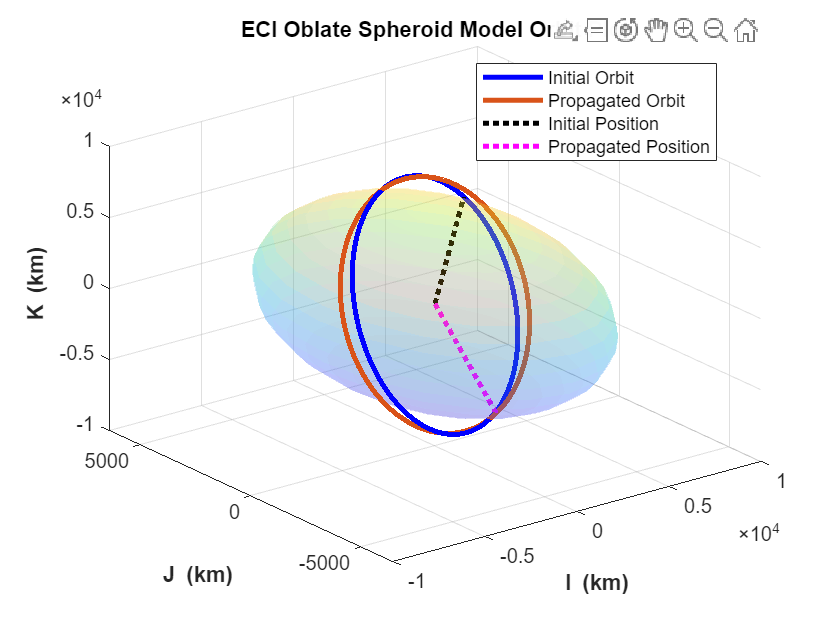

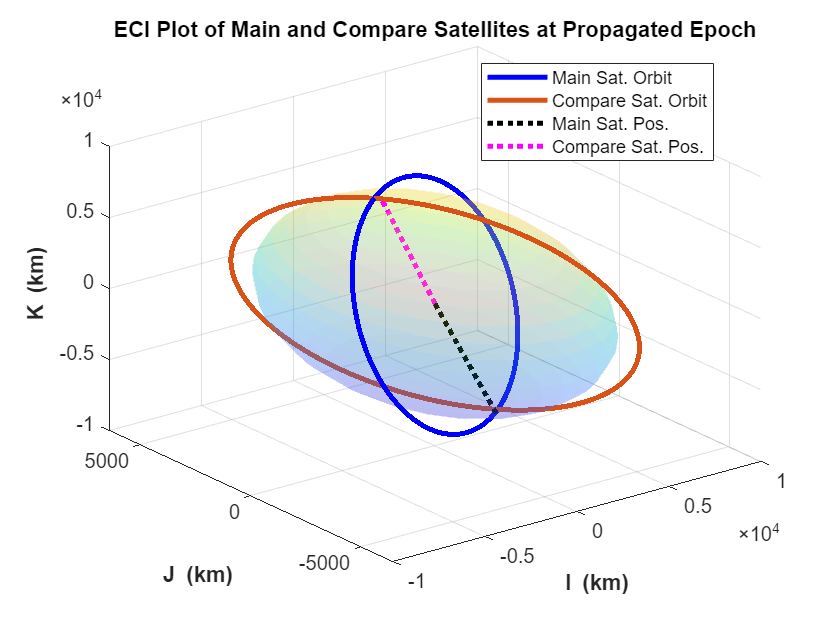




% Call the figures function to create the following two plots:
% --> A plot of the main satellite's initial and propagated orbits and
% positions
% --> A plot of the main satellite's propagated orbit and position with the
% compare satellite's propagated orbit and position

figures(r0, v0, rf, vf, r_compare, v_compare, model)